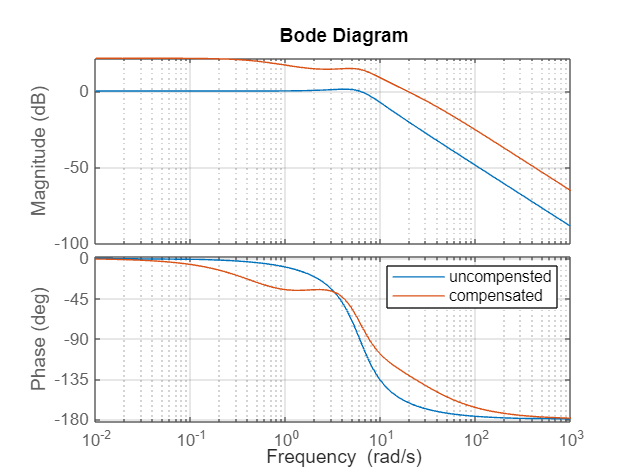

%NAME: WYCLIFFE MACHUKI OKENYE
%REG: EG209/106813/21
%CONTROL ASSIGNMENT

%% Case 1: G1(s) = 9/(s^2 + 4 s + 9)
s = tf('s');
G1 = 36/(s^2 + 6*s + 36);%%open loopTf for uncompensated sytem

% Proposed compensators
C_lead = 15*(s+2)/(s+25);%%lead comaparator
C_lag  = (s+6)/(s+0.6);
C_T= C_lead * C_lag;%%lead and lag in cascade

% Closed-loop (unity feedback)
T1 = feedback(C_T * G1, 1);%
% bode plot for uncompenated system and compensated system
figure;
bode(G1, C_T*G1); 
legend('uncompensted','compensated');
grid on;

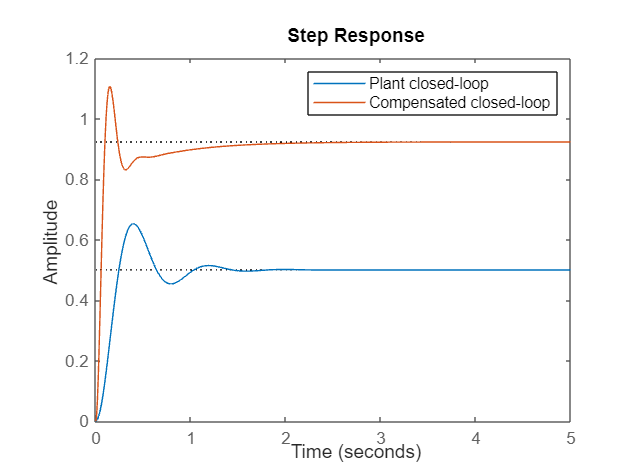

Step info for compensated case 1:


         RiseTime: 0.0657
    TransientTime: 1.2025
     SettlingTime: 1.2025
      SettlingMin: 0.8308
      SettlingMax: 1.1059
        Overshoot: 19.8100
       Undershoot: 0
             Peak: 1.1059
         PeakTime: 0.1515



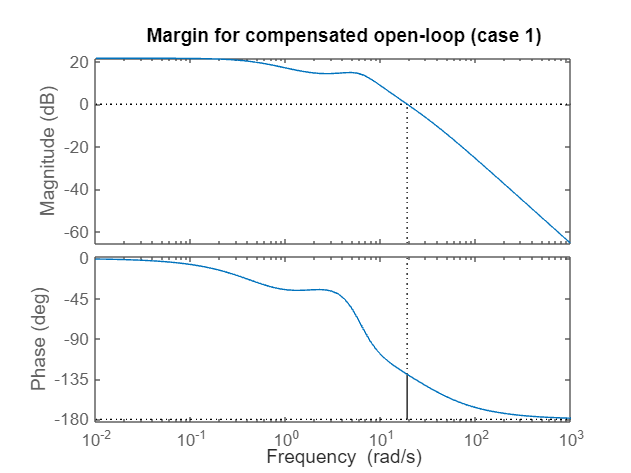

%%step polots for uncompensatedand fully_compensted system
figure; 
step(G1/(1+G1), T1); 
legend('Plant closed-loop','Compensated closed-loop');